1.读取一个图像文件，并显示图像；

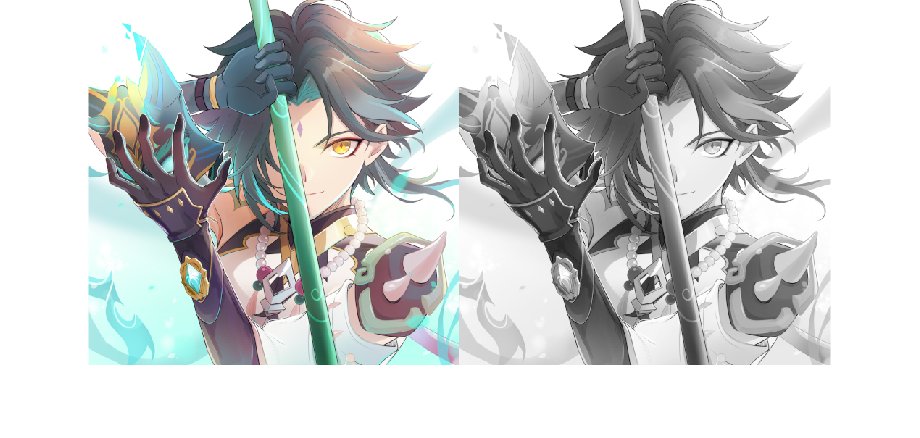

im = imread("yaksha.jpg");
img = rgb2gray(im);
imshowpair(im, img, "montage");

2.计算图像的直方图（不可调用imhist等函数，需自行实现从图像到直方图的计算），显示该直方图； 

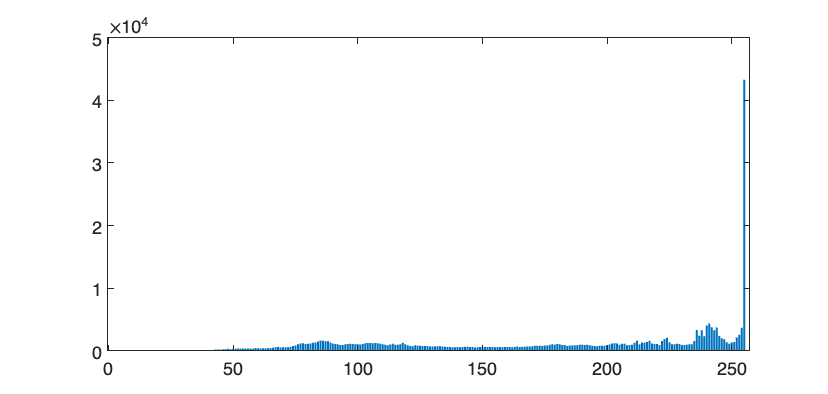

his = zeros(1, 256, "uint64");
[h, w] = size(img);
for i = 1:h
    for j = 1:w
        his(img(i, j)) = his(img(i, j)) + 1;
    end
end
bar(his)